max_torque = 8.2583

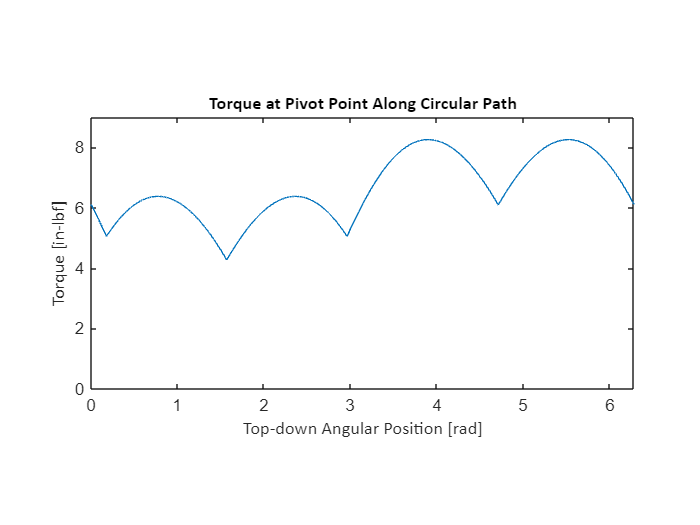

Vshaft_len = 50; % mm
a = torque_calc((Vshaft_len+15)/1000); % N-m

function final_t_max = torque_calc(L)
    % create lists of size 10000 for a high resolution of data points
    size = 10000;
    
    % create an array of spherical coordinates, inclined 20 degrees from vertical
    % and sweeping around the vertical axis
    theta = 20*pi/180;
    phi = linspace(0, 2*pi, size);
    
    % create a list to hold the direction vector perpendicular to the face of
    % the platform in an XYZ coordinate system
    xyz_coord_list = zeros(3,size);
    
    % create a list to hold the direction vector parallel to the face of the
    % platform, that points directly towards the vertical axis, so that if
    % the platform's face moves in that direction it will return to vertical
    center_perp_coord_list = zeros(3,size);
    
    % create a list to hold the direction vector perpendicular to the previous
    % two vectors, such that rotation along that axis will return the
    % platform's face to the vertical position
    flat_perp_coord_list = zeros(3,size);
    
    % create a list to hold theta3 and theta4 values for each coordinate, where
    % theta3 is the angular displacement of the horizontal shaft attached to
    % the differential bevel gear, and theta4 is the angular displacement of the 
    % gear on that axis
    theta34_list = zeros(2, size); 
    
    % create a list to hold the angular velocity of the platform at each
    % position in both XYZ axes and principle axes, with the platform moving at 
    % maximum velocity away from the vertical axis
    w_mag = 17; % [rad/s]
    w_list_xyz = zeros(3,size);
    w_list_princ = zeros(3,size);
    
    % create a list to hold the angular acceleration of the platform at each
    % position in both XYZ axes and principle axes, with the platform moving at 
    % maximum acceleration towards the vertical axis
    a_mag = 16; % [rad/s^2]
    a_list_xyz = zeros(3,size); 
    a_list_princ = zeros(3,size); 
    
    % create a list to hold the derivative of the momentum vector at each
    % position in XYZ axes and principle axes [N-m]
    H_d_list_xyz = zeros(3,size); 
    H_d_list_princ = zeros(3,size); 
    
    % create a list to hold the torque supplied to the pivot point by the
    % motors in XYZ coordinates for each position, and a list of the maximum 
    % torque experienced by either motor [N-m]
    T_mot_list = zeros(3,size); 
    max_torque_list = zeros(1,size); 
    
    % Mass, radius, and height for the frame, horizontal shaft, vertical shaft, platform, and differential bevel gear
    m = [15.74/1000, (239.54/1000), (3.77/1000), 2.72155, (11.592/1000)];  % [kg]
    r = [0, (7.5/1000), (10/1000), (7/39.37), ((73/2)/1000)];  % [kg]
    h = [(30/1000), (170/1000), ((50+15)/1000), (.25/39.37), (8/1000)];  % [m]
    % width of the frame
    w1 = (120/1000);  % [m]
    % thickness of the frame
    t1 = (4.43/1000);  % [m]
    % distance from center of mass to origin for platform
    dz4 = (15+50+(.25*25.4))/1000;  % [m]
    % distance from center of mass to origin for differential bevel gear
    dy5 = (73/2)/1000;  % [m]
    
    % useful mass values for calculating moments of intertia for the frame
    mt = ((2*w1*t1)/( (w1^2) - (w1-2*t1)^2))*m(1);
    ms = m(1)-mt;
    
    % X, Y, and Z moments of inertia for the differential system
    IxxL = [((ms/12)*( ((w1-2*t1)^2) + (h(1))^2)) + ((mt/12)*((t1^2)+(h(1)^2)+(((w1-t1)/2)^2))), ...
             (m(2)/12)*((3*(r(2)^2))+(h(2)^2)), (m(3)/12)*((3*(r(3)^2))+(h(3)^2))+(m(3)*((h(3)/2)^2)), ...
             ((m(4)/12)*((3*(r(4)^2))+(h(4)^2)))+(m(4)*(dz4^2)), ((m(5)/12)*((3*(r(5)^2))+(h(5)^2)))+(m(5)*(dy5^2))];
    
    IyyL = [((ms/12)*( ((w1-2*t1)^2) + (h(1))^2)) + ((mt/12)*((t1^2)+(h(1)^2)+(((w1-t1)/2)^2))), ...
             ((m(2)/2)*(r(2))^2), (m(3)/12)*((3*(r(3)^2))+(h(3)^2))+(m(3)*((h(3)/2)^2)), ...
             ((m(4)/12)*((3*(r(4)^2))+(h(4)^2)))+(m(4)*(dz4^2)), ((m(5)/2)*(r(5))^2)];
    
    IzzL = [(m(1)/12)*( (2*(w1^2)) - (2*(w1 - (2*(t1)))^2) ), ...
             (m(2)/12)*((3*(r(2)^2))+(h(2)^2)), ((m(3)/2)*(r(3))^2), ...
             ((m(4)/2)*(r(4))^2), ((m(5)/12)*((3*(r(5)^2))+(h(5)^2)))+(m(5)*(dy5^2))];
    
    Ixx = IxxL(1)+IxxL(2)+IxxL(3)+IxxL(4)+IxxL(5);  % [kg*m^2]
    Iyy = IyyL(1)+IyyL(2)+IyyL(3)+IyyL(4)+IyyL(5);  % [kg*m^2]
    Izz = IzzL(1)+IzzL(2)+IzzL(3)+IzzL(4)+IzzL(5);  % [kg*m^2]
    
    % intertia tensor for the differential system (products of inertia are 0 so
    % this is the principle coordinate system)
    J = [Ixx, 0, 0;
         0, Iyy, 0;
         0, 0, Izz];
    
    % define a gravity vector
    grav = 9.81;  % [m/s^2]
    g = grav*[0, 0, 1];
    
    for i = 1:size
        % define XYZ coordinates for each spherical coordinate
        x = -sin(theta)*cos(phi(i));
        y = -sin(theta)*sin(phi(i));
        z = -cos(theta);
        
        % calculate theta3 and theta4 using the XYZ coordinate
        th3 = atan(-y/z);
        th4 = -(abs(x)/x)*atan( sqrt((x^2) / ((y^2)+(z^2))) );
        
        % create a transformation matrix to rotate coordinate system by theta3
        th3trans = [1,        0,          0;
                0, cos(th3), -sin(th3);
                0, sin(th3), cos(th3)];
        
        % create a transformation matrix to rotate coordinate system by theta4
        th4trans = [cos(th4),  0, sin(th4);
                0,         1,        0;
                -sin(th4), 0, cos(th4)];
        
        % define previously described direction and angular velocity/acceleration vectors
        xyz_coord = [x;y;z];
        center_perp_coord = [-x*abs(z)/sqrt(x^2+y^2); -y*abs(z)/sqrt(x^2+y^2); abs(z)*sqrt(x^2+y^2)/z];
        flat_perp_coord = cross(xyz_coord, center_perp_coord);
        theta34_vals = [th3; th4];
        w_xyz = -w_mag*flat_perp_coord;
        a_xyz = a_mag*flat_perp_coord;
    
        % use theta3 and theta4 transformation matrices to define angular
        % velocity and acceleration in principle coordinates
        w_princ = ((w_xyz\th3trans)'\th4trans)';
        a_princ = ((a_xyz\th3trans)'\th4trans)';
    
        % calculate momentum vector in principle coordinates
        H_princ = J*w_princ;  % [kg*m^2/s] = [N*m*s]
    
        % calculate momentum derivative vector in principle coordinates
        % and convert to XYZ coordinates
        H_d_princ = J*a_princ + cross(w_princ, H_princ);  % [kg*m^2/s^2] = [N*m]
        H_d_xyz = th3trans*th4trans*H_d_princ;  % [N*m]
        
        % v is a vector normal to the surface of the platform
        v = xyz_coord;
    
        % n is a vector parallel to the horizontal shaft which has rotated to
        % an angular displacement of theta3
        n = [0; cos(th3); -sin(th3)];
        
        % calculate the moment created by the masses and gravity, and subtract
        % it from the momentum derivative vector to find the torque supplied by
        % the motors
        T_mass = (cross(h(3)*v, m(4)*g)+cross((h(3)/2)*v, m(3)*g)+cross(h(2)*n, m(5)*g)+cross((h(2)/2)*n, m(2)*g))';  % [kg*m^2/s^2] = [N*m]
        T_mot = H_d_xyz - T_mass;  % [N*m]
        
        % Because the system is not truly 3DOF, 3DOF torques cannot be properly
        % split into 2DOF torques supplied by two motors. From calculations,
        % one component of the 2DOF torque (T3) is exactly equal to one axis of the 
        % 3DOF torque, so the other torque (T4) is broken into both the positive and
        % negative magnitude of the other two axes combined for comparison
        T3 = T_mot(1);
        T4_1 = sqrt((T_mot(3)^2)+(T_mot(2)^2));
        T4_2 = -T4_1;
        
        % T3 and T4 are converted into the motor torques, T1 and T2, of which there are 2
        % of each due to the 2 possible values of T4
        T1_1 = (T3+T4_1)/2;
        T1_2 = (T3+T4_2)/2;
        T2_1 = (T3-T4_1)/2;
        T2_2 = (T3-T4_2)/2;
        
        % the maximum of all possible torques for T1 and T2 for this
        % orientation is added to the maximum torque list
        t_max = max(abs([T1_1, T1_2, T2_1, T2_2]));
    
        % all computed values are added into their respective lists for
        % examination if necessary
        xyz_coord_list(:,i) = xyz_coord;
        center_perp_coord_list(:,i) = center_perp_coord;
        flat_perp_coord_list(:,i) = flat_perp_coord;
        theta34_list(:,i) = theta34_vals;
        w_list_xyz(:,i) = w_xyz;
        a_list_xyz(:,i) = a_xyz;
        w_list_princ(:,i) = w_princ;
        a_list_princ(:,i) = a_princ;
        H_d_list_princ(:,i) = H_d_princ;
        H_d_list_xyz(:,i) = H_d_xyz;
        T_mot_list(:,i) = T_mot;
        max_torque_list(:,i) = t_max;
    end
    
    % the maximum torque from the list of the maximum motor torque at each
    % location is selected, and displace in N-m and in-lbf
    final_t_max = max(max_torque_list);  % [N*m]
    max_torque = 8.857916*final_t_max  % [in-lbf]
    
    
    angle = linspace(0, 2*pi, size);
    torque = 8.857916*max_torque_list;
    figure(1)
    plot(angle, torque)
    pbaspect([2 1 1])
    xlim([0 2*pi])
    ylim([0 9])
    
    title('Torque at Pivot Point Along Circular Path', 'fontname','calibri')
    xlabel('Top-down Angular Position [rad]', 'fontname','calibri')
    ylabel('Torque [in-lbf]', 'fontname','calibri')
end%


% ALL OF THE BELOW CODE IS NOT USED FOR TORQUE CALCS

% th3 = .02;
% th4 = 1.5;
% princ_coords = [0; 0; -1];
% th3trans = [1,        0,          0;
%             0, cos(th3), -sin(th3);
%             0, sin(th3), cos(th3)];
% 
% 
% th4trans = [cos(th4),  0, sin(th4);
%             0,         1,        0;
%             -sin(th4), 0, cos(th4)];
% 
% xyz_coords = th3trans*th4trans*princ_coords;
% 
% th3 = atan(-xyz_coords(2)/xyz_coords(3));
% th4 = -(abs(xyz_coords(1))/xyz_coords(1))*atan( sqrt((xyz_coords(1)^2) / ((xyz_coords(2)^2)+(xyz_coords(3)^2))) );
% 
% old_princ_coords = ((xyz_coords\th3trans)'\th4trans)';
% w1=1;
% w2=2;
% th1i=0;
% th2i=0;
% th3i=0;
% r1 = 1;
% r2 = 1;
% ro1 = 1;
% v_r1 = r1*[0;cos(th1i);-sin(th1i)];
% v_r2 = r2*[0;cos(th2i);-sin(th2i)];
% v_w1 = [w1;0;0];
% v_w2 = [w2;0;0];
% v_ro1 = [-ro1;0;0];
% v_ro2 = -v_ro1;
% 
% W = (2*v_ro1) + v_r1 - v_r2;
% X = cross(v_w1,v_r1) - cross(v_w2,v_r2);
% 
% v_w4 = [0;-X(3)/W(1);X(2)/W(1)];
% test_w4 = v_w4(2)*W(3)-v_w4(3)*W(2) - X(1);
% 
% 
% Y = 0.5*(v_r1+v_r2);
% Z = cross(v_w1,v_r1)-cross(v_w4,v_ro1+.5*(v_r1-v_r2));
% v_w3a = [Z(3)/Y(2); 0; 0];
% test_w3 = [-Z(2)/Y(1); 0; 0];
% 
% t = linspace(0,1,1000)';
% v_w1sim = [t,w1*ones([1000,1]),zeros([1000,1]),zeros([1000,1])];
% v_w2sim = [t,w2*ones([1000,1]),zeros([1000,1]),zeros([1000,1])];
% v_ro1sim = [t,-ro1*ones([1000,1]),zeros([1000,1]),zeros([1000,1])];
% r1_sim = [t, r1*ones([1000,1])];
% r2_sim = [t, r2*ones([1000,1])];
% simu = sim('kinematics_sim.slx');
% tsim = simu.tout;
% w1sim = simu.v_w1_sim;
% w2sim = simu.v_w2_sim;
% w3sim = simu.v_w3_sim(:,:)';
% w3sim1 = simu.v_w3_sim1(:,:)';
% w4sim = simu.v_w4_sim(:,:)';
% w4sim1 = simu.v_w4_sim1(:,:)';